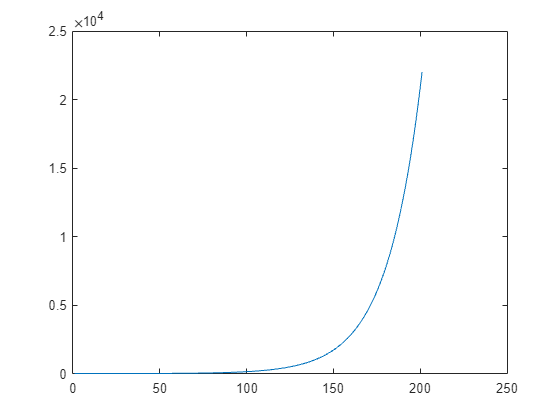

%exe2
x = 0:0.05:10;
y = exp(x);
plot(y)

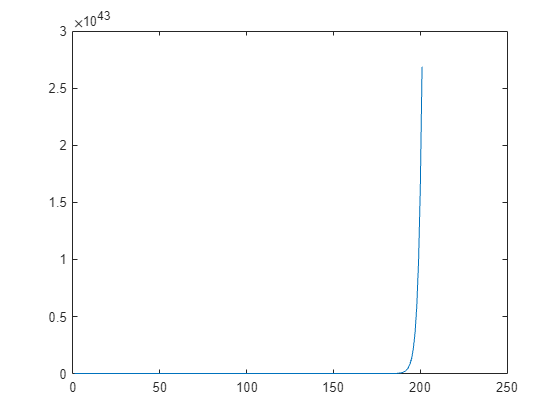

a = 10;
plot(exp(a*x))

z = log(y)

z =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


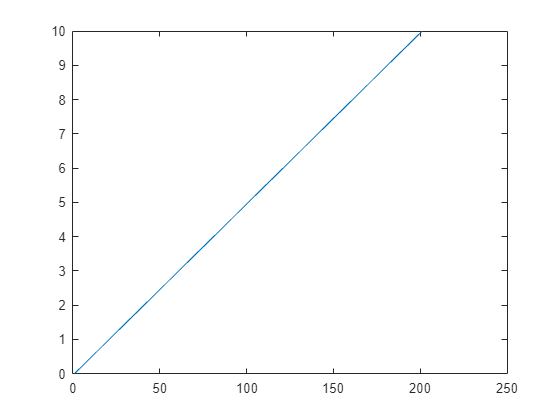

plot(z);

plot(x);

%doc diff;
res = diff(y)/0.05

res = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012


%diff(y)
plot(y);

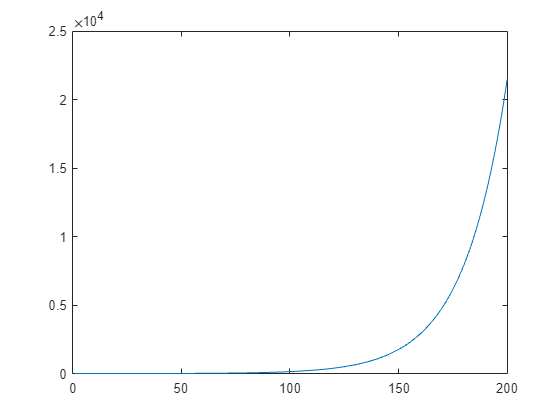

plot(res);

%help quad, use funtun @
res = @(x) exp(x);
result = quad(res, 0, 1)

result = 1.7183

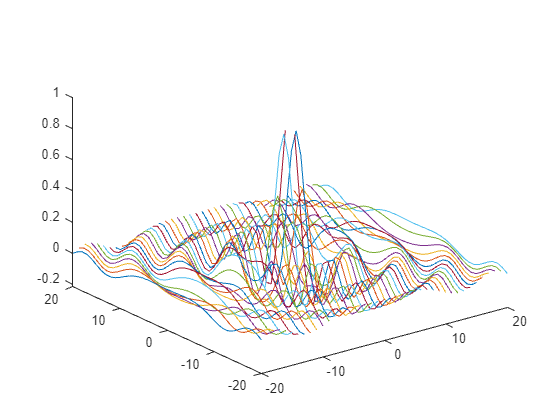

%doc meshgrid
x = -20:20;
y = -20:20;
[X,Y] = meshgrid(x,y);
f = sin(sqrt(X.^2 + Y.^2))./sqrt(X.^2+Y.^2);
plot3(X,Y,f)

%help plot3

% % 定义x和y的范围
% [x, y] = meshgrid(-20:0.5:20, -20:0.5:20);
% % 计算f(x, y)
% f = exp(x + y) ./ (exp(x) + exp(y));
% figure;
% plot3(x, y, f);


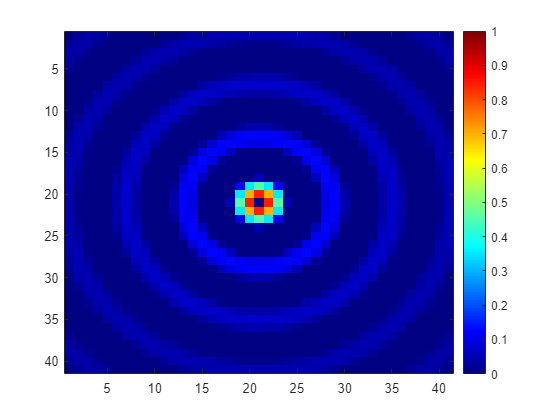

% 使用imagesc进行2D可视化
figure;
imagesc(f);
colorbar;
colormap('jet');
caxis([0 1]);

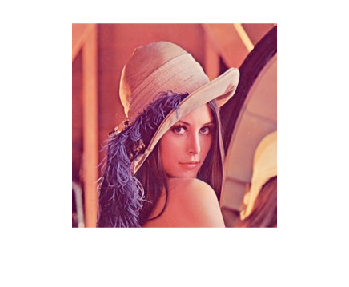

%image(lena_colour.jpg)
% 导入图像
lena_colour = imread('C:\Users\HP\Desktop\上课\人工智能b\scrip\lena_colour.jpg');
figure;
imshow(lena_colour);

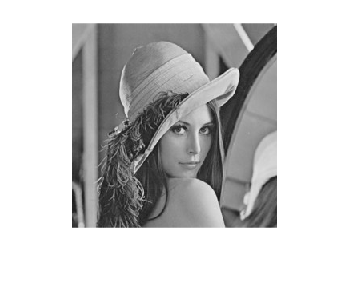


% 转换为灰度图像
lena_greyscale = rgb2gray(lena_colour);
figure;
imshow(lena_greyscale);

 
imwrite(lena_greyscale, 'lena_greyscale.png');
imshow(lena_greyscale);

figure;

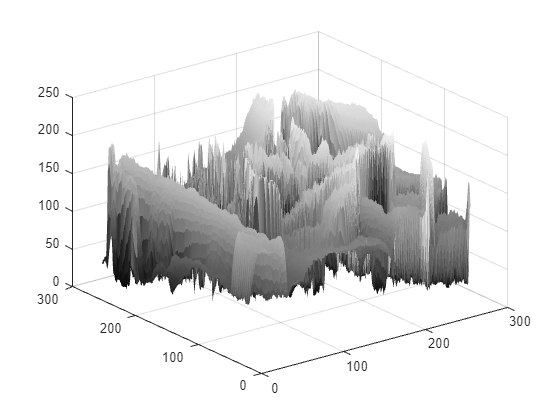


surf(lena_greyscale, 'LineStyle', 'none');
% view(2); 
colormap('gray');

imshow(lena_greyscale);
axis off; 


figure;

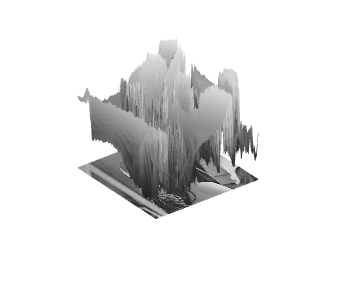

figure
% 普通图像

% 表面图
lena_greyscale = imread('lena_greyscale.png');
surf(lena_greyscale, 'LineStyle', 'none');
hold on
imshow(lena_greyscale);
colormap('gray');